clearvars

Load training data

loadtrainingdata

Define search space for Bayesian optimization

optimVars = [
    optimizableVariable('lr',[0.15,0.25])
    optimizableVariable('mb',[150,350],'Type','integer')
    optimizableVariable('dr',[10,40],'Type','integer')
    optimizableVariable('vf',[5,20],'Type','integer')
    optimizableVariable('mo',[0.8,0.99])
];
mm = 'sgdm';
co = 5;
MaxEpochs = 100;

Objective function

objFcn = @(x)trainAndValidate(x,trainDS,valDS);

Run Bayesian optimization

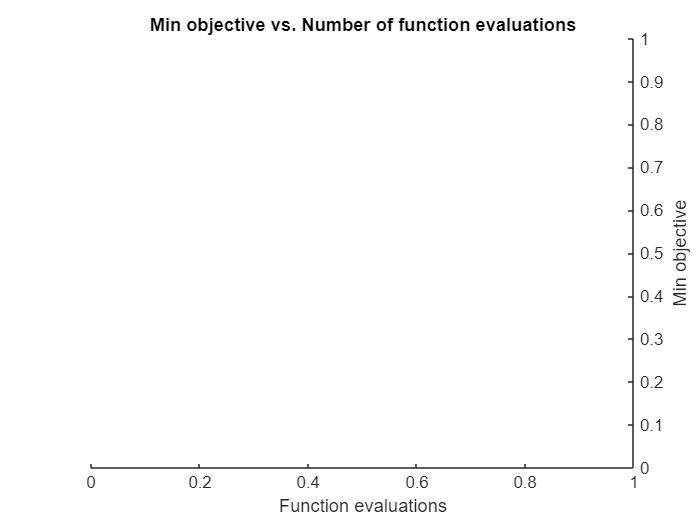

ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.8275
                InitialLearnRate: 0.1805
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 40
                   MiniBatchSize: 187
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 15
              ValidationPatience: 25
             ObjectiveMetricName: 


=== Running Training 1 ===


results = bayesopt(objFcn,optimVars, ...
    'MaxObjectiveEvaluations',30, ...
    'AcquisitionFunctionName','expected-improvement-plus');

Get best hyperparameters

bestParams = results.XAtMinEstimatedObjective;

% Map parameters to variables you use in  training scripts
lr  = bestParams.lr;
mb  = bestParams.mb;
dr  = bestParams.dr;   % dropout
vf  = bestParams.vf;   % validation frequency
mo  = bestParams.mo;   % momentum

numRuns = 5;

% Preallocate arrays
accTest = zeros(numRuns+2,1);
macroPrecisionTest = zeros(numRuns+2,1);
macroRecallTest = zeros(numRuns+2,1);
macroF1Test = zeros(numRuns+2,1);

for run = 1:numRuns
    fprintf('=== Run %d ===\n', run);
    conv4layers;              

    createTrainingOptions("sgdm", lr, x.dr, MaxEpochs, mb, valDS, vf, mo, 1);

    runfile

    accTest(run)            = acc;
    macroPrecisionTest(run) =  macroPrecision;
    macroRecallTest(run)    = macroRecall;
    macroF1Test(run)        = macroF1;

    figure('Name',sprintf('Run %d Confusion Matrices', run),'NumberTitle','off');

    % === Training ===
    subplot(1,3,1);  % 1 row, 3 columns, first subplot
    YPredTrain = classify(net, trainDS);
    YTrain = trainDS.Labels;
    cmTrain = confusionmat(YTrain, YPredTrain);
    confusionchart(cmTrain);
    title(sprintf('Train CM (Run %d)', run));

    % === Validation ===
    subplot(1,3,2);  % second subplot
    YPredVal = classify(net, valDS);
    YVal = valDS.Labels;
    cmVal = confusionmat(YVal, YPredVal);
    confusionchart(cmVal);
    title(sprintf('Validation CM (Run %d)', run));

    % === Test ===
    subplot(1,3,3);  % third subplot
    YPredTest = classify(net, testDS);
    YTest = testDS.Labels;
    cmTest = confusionmat(YTest, YPredTest);
    confusionchart(cmTest);
    title(sprintf('Test CM (Run %d)', run));
end

accTest(run)            =   mean(accTest(1:numRuns));
macroPrecisionTest(run) =   mean(macroPrecisionTest(1:numRuns));
macroRecallTest(run)    =   mean(macroRecallTest(1:numRuns));
macroF1Test(run)        =   mean(macroF1Test(1:numRuns));
accTest(run)            =   std(accTest(1:numRuns));
macroPrecisionTest(run) =   std(macroPrecisionTest(1:numRuns));
macroRecallTest(run)    =   std(macroRecallTest(1:numRuns));
macroF1Test(run)        =   std(macroF1Test(1:numRuns));

function obj = trainAndValidate(x,trainDS,valDS)
    global options
    persistent expNum
    if isempty(expNum)
        expNum = 1;
    else
        expNum = expNum + 1;
    end
    createTrainingOptions("sgdm", x.lr, x.dr, 100, x.mb, valDS, x.vf, x.mo, 1)
    
    conv4layers 
   
    runfile 
    
    YPredTrain = classify(net, trainDS);
    YTrain     = trainDS.Labels;
    trainAcc = mean(YPredTrain == YTrain);

    YPred = classify(net,valDS); 
    YVal  = valDS.Labels;
    valAcc = mean(YPred == YVal);
    

   Objective: 

- maximize validation acuarrcy

- minimize validation error 

    lambda = 0.25;
    obj = (1 - valAcc) + lambda * max(gap,0);
end
